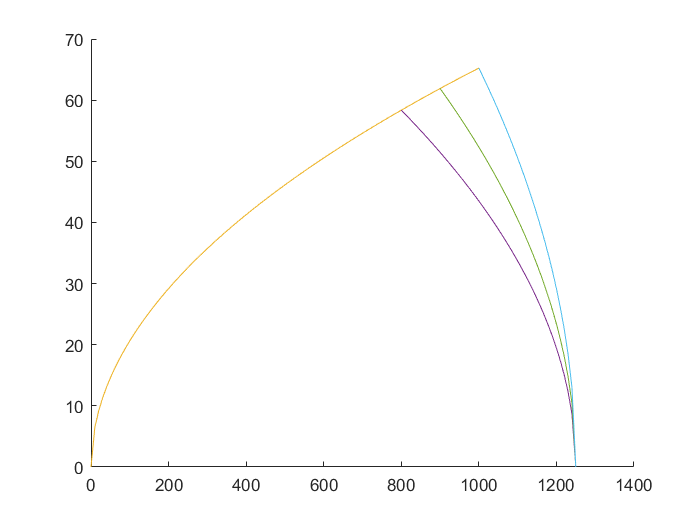

% the following plots and equations model the velocity vs distance 
% ideal behaviour of the hyperloop pod 

% should be used for analysis purposes and esstimations only, because
% the model might be incomplete

% here is ploted based on the respective intervals
% of each acceleration, the speed of the pod 

% three cases have been taken: 1. it starts braking at 800m
%                              2. it starts braking at 900m
%                              3. it starts braking at 1000m


clear
clc
%input arguments 

mass = 200; %in Kg

Force = 425.754; %in Newton

s = [800, 900, 1000]; %different values for braking distance

d=1250; %the total distance

acceleration = pod_acceleration(mass,Force);

top_Speed = top_speed(acceleration,s);

decceleration = acceleration_of_brakes(top_Speed,s,d);

braking_force = decceleration.*mass;

x11= 0:10:800;
x12= 0:10:900;
x13= 0:10:1000;

x21 = 800:10:1250;
x22 = 900:10:1250;
x23 = 1000:10:1250;

v11 = sqrt(2*acceleration.*x11);
v12 = sqrt(2*acceleration.*x12);
v13 = sqrt(2*acceleration.*x13);

v21 = sqrt(top_Speed(1)^2-2*decceleration(1)*(x21-s(1)));%case 1 
v22 = sqrt(top_Speed(2)^2-2*decceleration(2)*(x22-s(2)));% case 2
v23 = sqrt(top_Speed(3)^2-2*decceleration(3)*(x23-s(3)));% case 3 

hold on 

plot(x11,v11);
plot(x12,v12);
plot(x13,v13);

plot(x21,v21);
plot(x22,v22);
plot(x23,v23);